# Práctica 2: medida y calibración

## 1. Variación de la energía a lo largo del tiempo

### 1.1 Cálculo del valor eficaz (*rms*) de una señal

La unidad de medida habitual cuando trabajemos con señales eléctricas o de sonido es el **valor eficaz** (*rms, Root Mean Square*).

El valor *rms* de una señal, en el intervalo [t1 t2], es $x_{eff}=x_{rms}= \sqrt{\overline{x^2}} = \sqrt{\frac{1}{T} \int_{t_1}^{t_2} x^2(t) \, \mbox{d}t}$, con T = t2-t1. Si la señal es discreta, el valor eficaz, en el intervalo [n1 n2], se estima como: 

            $\hat{x}_{rms}= \sqrt{\frac{1}{N} \sum_{n=n_1}^{n=n_2} x[n]^2 }$,

donde N es el número de muestras del intervalo.

Crea una función nueva con esta cabecera:

            *function outputRMS = MyRMScalculation(signal);*

y completa estas líneas en el cuerpo de la función para que devuelva el valor eficaz de la señal de entrada:

*            % RMS calculation. *

*            % Use the 'sum' command.*

*            % Do NOT use a 'for' loop.*

*            outputRMS = ?????*

Probemos ahora si funciona según lo previsto. Al usar como entrada:

        *    >> outputRMS = MyRMScalculation(1:5)*

deberíamos obtener este valor:

        *    outputRMS =*

*                    3.3166*

Comprueba que este resultado se corresponde con el que obtienes al calcularlo manualmente.

Genera un tono puro de 200 Hz de 5 segundos, de amplitud 1, que comienza en el instante t = 0 segundos. Suponemos una frecuencia de muestreo de 6 kHz. Almacénalo en la variable *tono200Hz*.

% Generar un tono puro de 200 Hz
% Parámetros
f1 = 200; % Frecuencia del tono en Hz
fs = 6000; % Frecuencia de muestreo en Hz
T = 5; % Duración en segundos

% Vector de tiempo
t = 0:1/fs:T-1/fs;

% Generar el tono puro
tono200Hz = sin(2 * pi * f1 * t);

% Calcular el RMS del tono generado
outputRMS = MyRMScalculation(tono200Hz);
disp(['RMS of 200 Hz tone is: ', num2str(outputRMS)]);

Representa a la vez la señal *tono200Hz* y su valor eficaz. Usa el comando *yline*.

% Parámetros
f1 = 200; % Frecuencia del tono en Hz
fs = 6000; % Frecuencia de muestreo en Hz
T = 5; % Duración en segundos

% Vector de tiempo
t = 0:1/fs:T-1/fs;

% Generar el tono puro
tono200Hz = sin(2 * pi * f1 * t);

% Calcular el RMS del tono generado
tono200Hz_rms = MyRMScalculation(tono200Hz);

% Graficar la señal y su valor RMS
figure;
plot(t, tono200Hz);
hold on;
yline(tono200Hz_rms, 'r--', 'RMS Value');
title('Tono puro de 200 Hz y su valor eficaz (RMS)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Tono 200 Hz', 'Valor RMS');
hold off;

Representa sólo los tres primeros periodos, usando *xlim.*

% INSERTE EL CÓDIGO AQUÍ:
% xlim(???

Carga la señal x2, generada usando la misma frecuencia de muestreo que estamos usando.

% INSERTE EL CÓDIGO AQUÍ:


Comprueba que nos sirve el mismo eje temporal t, que estamos usando con la señal *tono200Hz*

% INSERTE EL CÓDIGO AQUÍ:

Es más cómodo, en estos casos, usar el comando *whos*, para comprobar qué variables tienes cargadas, de qué tipo son y qué tamaño tienen. 

Representa a la vez la señal x2 y su valor eficaz, como has hecho antes con la señal *tono200Hz*. 

% INSERTE EL CÓDIGO AQUÍ:
%  x2_rms = ...
% plot(???)
% (...)
% yline(x2_rms, ???

Observa el comienzo de la señal x2 y su parte final. ¿El valor eficaz que has calculado tiene sentido si queremos observar variaciones de energía en la señal a lo largo del tiempo? ¿Por qué?

¿Qué unidades tiene el tono *tono200Hz* que acabas de generar? ¿Qué unidades tiene la señal *x2* que has cargado?

### 1.2 Incorporando el cálculo del valor eficaz a nuestra estructura de procesado

Cuando manejamos señales que pueden cambiar su amplitud media a lo largo del tiempo, es interesante calcular su energía en ventanas más cortas.

Como ya tenemos una función que calcula el valor cuadrático medio (*rms*), podemos integrarla en nuestra estructura de procesado por tramas.

Salva la función *FrameProcessing* a un archivo llamado *FrameRMScalculation*, y modifica su cabecera:

*            function processedSignal = FrameRMScalculation(signal,Nframe, Noverlap)*

En esta función lo único que tenemos que hacer es incluir el procesado que queremos:

        *    % Here comes the frame processing*

*            processedFrame = MyRMScalculation(frameSignal);*

Y ya estaría. Bueno, no, primero hay que comprobar que funciona.

Al llamar a la función con estos valores:

    *    >> processedSignal = FrameRMScalculation((1:5)',2,1)*

deberíamos obtener estos valores en la salida *processedSignal*:

            *totalNframes =*

            *     5*

            *Frame number 1.....   1  2*

            *Frame number 2.....   2  3*

            *Frame number 3.....   3  4*

            *Frame number 4.....   4  5*

            *ans =*

            *    1.5811    2.5495    3.5355    4.5277*

Fijaos que nos devuelve un único valor por cada trama de procesado, ya que la función *MyRMScalculation* es lo que hace. 

De hecho, si procesáramos el seno de 200 Hz que teníamos guardado en la señal tono200Hz como una sola trama debería darnos el valor teórico esperado. Comprobadlo:

    *    >> processedSignal = FrameRMScalculation(tono200Hz,length(tono200Hz),0);*

Calcula el valor eficaz teórico de un tono de 200 Hz, de amplitud 1, en una señal continua (*analógica*), ¿obtenemos el mismo valor?

% INSERTE EL CÓDIGO AQUÍ:

% theoreticalRMSvalue = ????

Calculemos ahora el valor eficaz de la señal x2 que habíamos cargado, pero ahora de forma progresiva a lo largo de la señal. Por ejemplo, con tramas de 100 ms... ¿cuántas muestras debemos elegir?

% Insert code
% fs = 6e3;
% frameSize = ?????

Analiza ahora el valor eficaz de la señal x2 con ese tamaño de trama, sin solapar.

Representa solamente el valor eficaz, representando con un asterisco sus valores:

% Insert code
%Noverlap = 0;
%processedSignal = FrameRMScalculation(???
%figure;plot(processedSignal,'-*');shg;


¿Representa mejor lo que ocurre en la señal esta forma de calcular el valor eficaz? Discute por qué.

**EXTRA:**

Intenta representar a la vez la forma de onda de la señal x2 y el resultado del valor eficaz a lo largo del tiempo, ¿qué problema te encuentras? ¿Cómo lo solucionarías para poder representarlas en la misma figura?

% Insert code
% t2 = ?????
% figure();plot(t,x2);
% hold on; plot(t2, processedSignal, '-*'); 

### 1.3 Resumen

En esta sección 1 hemos:

- calculado el valor eficaz de una señal

- programado una función *FrameRMScalculation(...)*, usando nuestra estructura de procesado en tramas, para calcular la evolución del valor eficaz a lo largo de la señal.

## 2. Calibración 

### 2.1 Sistema de medida: sistema analógico y sistema digital

Cuando queremos usar un sistema de procesado digital para analizar una señal, siempre tenemos una parte que trabaja con señales analógicas (continuas), lo que podemos llamar un **sistema analógico**, y una parte que trabaja con señales discretas y cuantificadas, lo que podemos llamar un **sistema digital**.

El sistema analógico hace de *front-end*, convirtiendo la variable física que queremos medir en una señal eléctrica. El sistema digital convierte esta señal eléctrica en una señal discreta y cuantificada (lo que solemos llamar ***señal digital***), sobre la que realizará sus cálculos. Lo realiza el llamado conversor analógico-digital (A/D).

Habitualmente, los sistemas de medida no suelen reconstruir otra vez una señal analógica, aunque esto sería posible usando un conversor digital-analógico (D/A).

                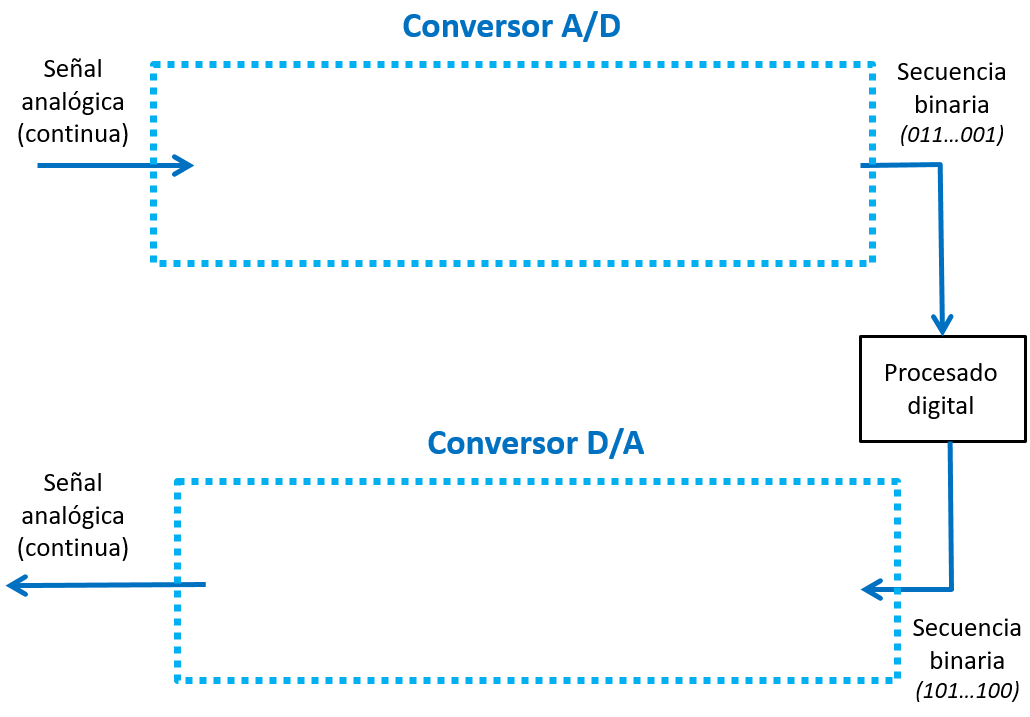

### 2.2 Sistema analógico: transducción acústico-eléctrica y sensibilidad de un micrófono

Si queremos medir señales acústicas, lo primero que debemos hacer es convertirlas en una señal eléctrica. Esto se consigue usando un micrófono, que es un transductor que convierte la energía acústica en energía eléctrica. 

                    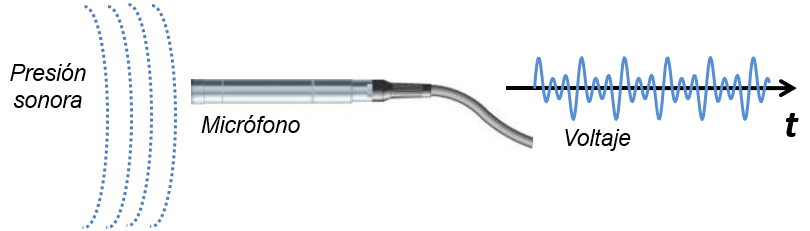

Esa transducción viene definida, principalmente, por lo que llamamos ***S***, la **sensibilidad del micrófono**. Esta sensibilidad relaciona la energía eléctrica conseguida cuando excitamos el micrófono con una energía acústica determinada gracias a la siguiente fórmula:

        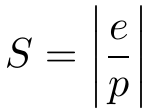

donde ***e*** es el voltaje que obtenemos al presentar el micrófono a una presión sonora ***p***. **Se consideran siempre valores eficaces (*****rms*****).**

**La sensibilidad S es dependiente tanto de la frecuencia de trabajo como del ángulo de llegada** del frente de onda acústico al micrófono, ya que los micrófonos suelen ser directivos, es decir, su sensibilidad varía con el ángulo de llegada y la frecuencia. Podemos decir que la sensibilidad del micrófono, S, la podemos calcular tomando en cuenta tres elementos:

-  La **sensibilidad nominal**, que es la sensibilidad del micrófono en su eje acústico (0º de llegada), a 1 kHz. Podemos encontrar este parámetro expresado tanto en unidades naturales, mV/Pa, como en unidades logarítmicas dBV/Pa.

-    La variación con la frecuencia en el eje acústico (0º de llegada). Es la llamada "**respuesta en frecuencia**". Habitualmente expresada en dB.

-    La variación con la frecuencia y el ángulo de llegada. Es el llamado "**patrón de captación**" o "respuesta polar". Habitualmente expresado en dB.

Estos tres elementos se combinan de la siguiente forma, si estamos usando unidades logarítmicas.

        

Por ejemplo, supongamos que tenemos un micrófono cuya sensibilidad nominal (0º, 1kHz) es S = 1.6 mV/Pa y sus especificaciones son:

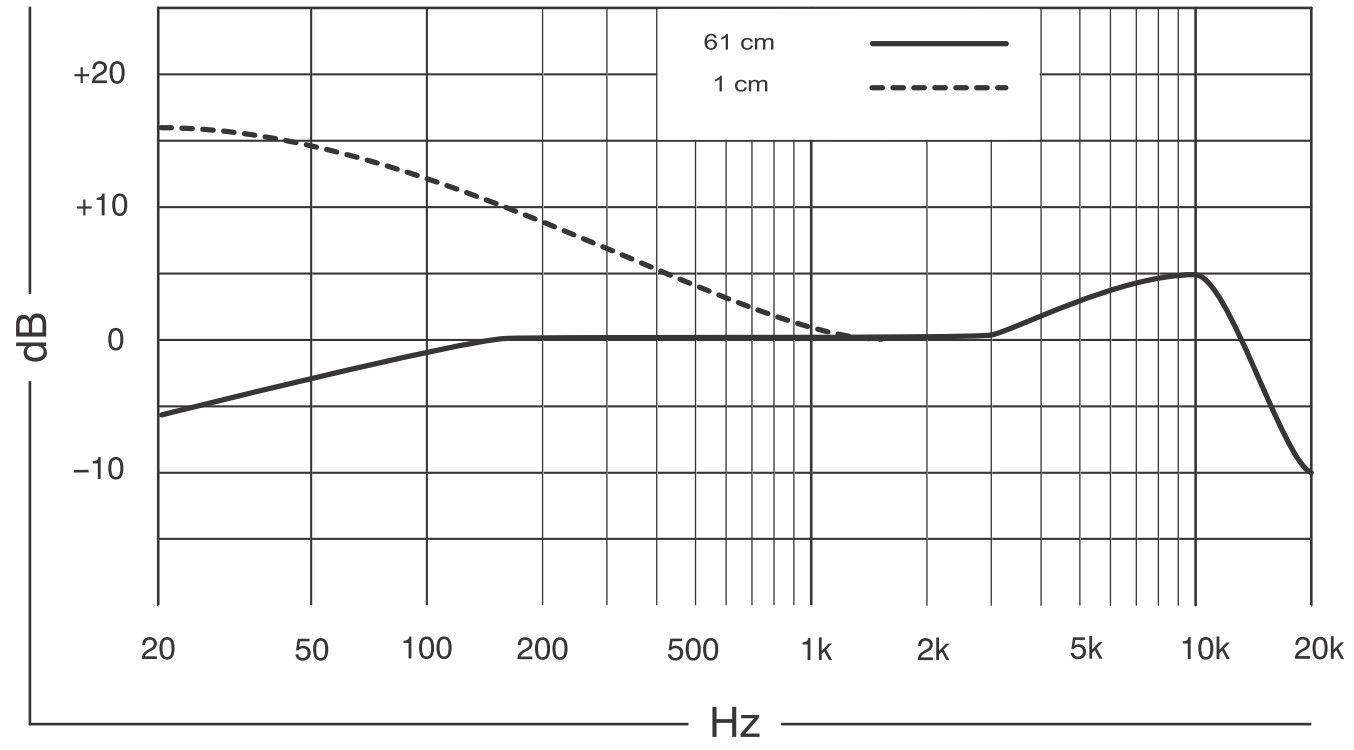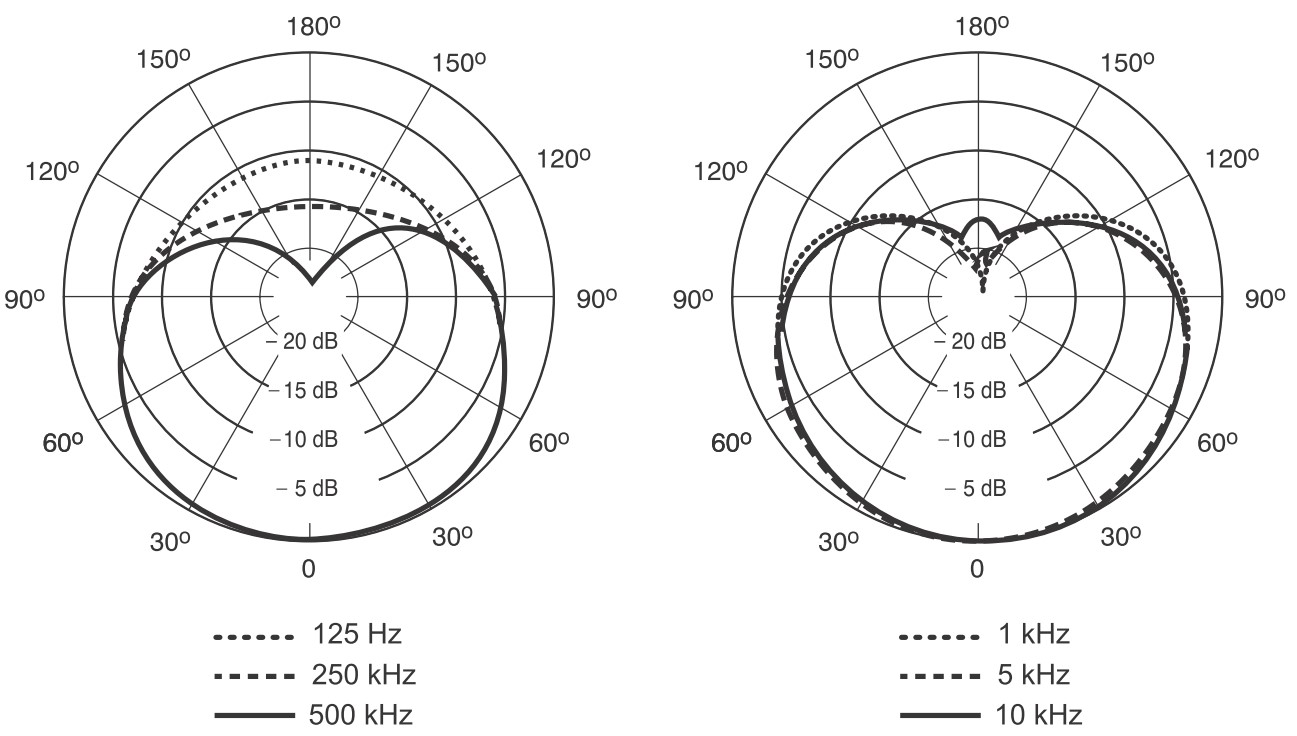

**Calculemos su sensibilidad S para una frecuencia de 10 kHz y 120º de ángulo de llegada. Suponemos una distancia hasta la fuente de sonido mayor que 61 cm, por lo que al micrófono no le afecta el "efecto proximidad".**

Inicializamos primero estas variables, que se corresponden con la sensibilidad nominal en unidades naturales, *S_1kHz_un*, en *V/Pa*, y las variaciones en decibelios debidas a la frecuencia de trabajo y el ángulo de llegada. Aproxima estas variaciones al valor entero en decibelios más próximo. Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% Insert code
% S_1kHz_un = 1.6e-3;  % V/Pa
% deltaS_f = ???        % units???
% deltaS_theta = ???        % units???

Pasamos la sensibilidad nominal a unidades logarítmicas, a *dBV/Pa*, por ejemplo.

% Insert code
% S_1kHz_log = ???  % dBV/Pa


Para encontrar la sensibilidad total sólo tenemos que sumar los términos correspondientes:

% Insert code
% S_log = ???  % dBV/Pa


Asegúrate de que el resultado sea *S_log = -60.9176 dBV/Pa*. En las comprobaciones usaremos varios decimales, para evitar que se nos acumulen errores de cálculo, pero en las hojas de especificaciones los valores no se indican con tanta precisión.

### 2.3 Conexión entre el sistema analógico y el sistema digital. 

La señal eléctrica de salida del micrófono suele pasar a través de un ajuste de ganancia G, para poder permitir lo que se denomina su "*calibración*", que veremos en breve.

Por lo tanto, el sistema con el que trabajaremos será similar a éste:

                    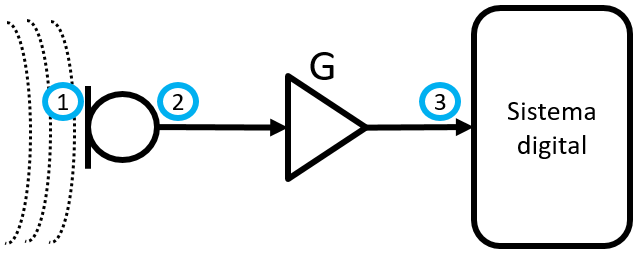

En el punto 1 tendremos presión sonora, el punto 2 será la salida del micrófono y, por tanto, una señal eléctrica, y el punto 3 también seguirá siendo una señal eléctrica. Todas son señales analógicas (continuas).

Vamos a suponer ahora que el micrófono es el presentado en el apartado 2.2. **Queremos saber qué voltaje aparecerá en el punto 3, en dBV, a la entrada del sistema digital, si presentamos un tono de 1 kHz, con un ángulo de llegada de 0º y una presión de 94 dB de nivel de presión sonora en el punto 1.** La ganancia G del amplificador es de 3 dB.

Primero, debemos saber el voltaje en el punto 2, para lo que necesitamos aplicar la sensibilidad del micrófono sobre la presión a la que está expuesto.

Calcula la sensibilidad del micrófono. Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% Insert code
% S_1kHz_un = 1.6e-3;  % V/Pa
% deltaS_f = ???  % units??
% deltaS_theta = ???  % units??
% S = ???  % units??


Calcula el voltaje, en unidades naturales, en el punto 2. Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% Insert code
% L_p1 = 94; % dBSPL
% p_1 = ??? % units??
% e_2 = ??? % units??


Calcula el voltaje en el punto 3. Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% Insert code
% G_log = 3; % dB
% e_2_log = ??? % units??
% e_3_log = ??? % units??


Asegúrate de que el resultado sea *e_3_log = -52.8970 dBV*.

### 2.4 Rango dinámico en el sistema digital. 

Recordemos que para definir el rango dinámico de un sistema debemos fijar los siguientes parámetros:

- Máximo valor útil: es el que define el comienzo de la llamada **zona de recorte** (*clip*). Cualquier valor más alto será "inservible", ya sea porque será truncado a este valor máximo, o bien porque su distorsión es tan grande que la salida no se considera válida para la aplicación.

- Mínimo valor útil: cualquier valor menor que éste será "inservible", sea porque será sustituído por este valor mínimo o porque el ruido de fondo existente haga que la salida no sea válida para la aplicación.

- Holgura (*headroom*): el nivel de la señal en cada momento puede ir cambiando, pero se suele definir el llamado **nivel nominal**, que es el nivel de trabajo para el que se suelen especificar las características de los equipos. La diferencia entre el valor máximo útil y este nivel nominal se denomina *headroom*.

- Relación Señal-a-Ruido (SNR): la diferencia de niveles entre el nivel de la señal y el ruido de fondo nos dice si tenemos un ruido de fondo razonablemente bajo en cada momento.

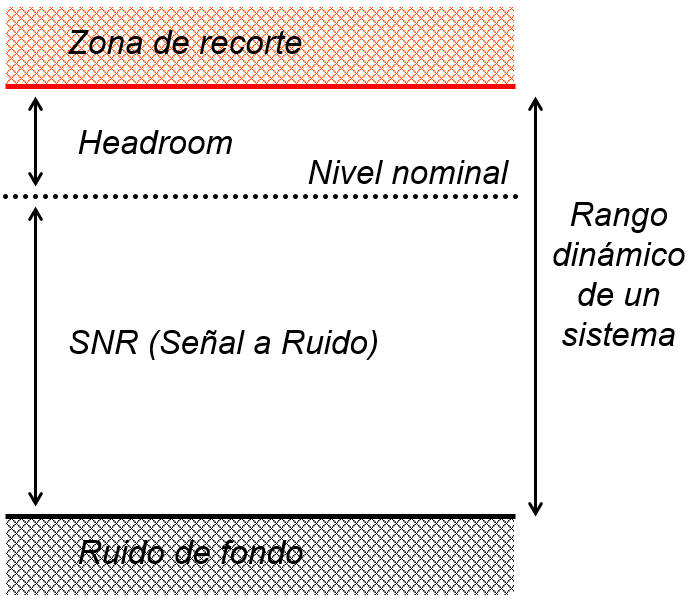 

En un sistema digital se puede definir también su rango dinámico:

- Máximo valor útil (***x_max***): será el máximo valor representable. Se suele considerar normalizado, por lo que suele ser un valor absoluto de "1", en unidades naturales.

- Mínimo valor útil: será el mínimo valor representable en valor absoluto. Suele ser el "0", en unidades naturales.

- Holgura (*headroom*): a priori no se suele especificar, y suele venir dada por la aplicación. Establece la relación con un valor nominal de la aplicación: ***x_nom***.

- Relación Señal-a-Ruido (SNR): se suele definir entre el máximo y el mínimo valor representable, considerando el número de bits dedicados a representar cada valor.

Y la relación con sus valores analógicos se suele establecer así (en unidades naturales):

, siendo *e_max* el máximo valor de voltaje considerado en la aplicación, y *e_nom* el que se considera como valor nominal.

Al ser una correspondencia directa entre los valores, se mantienen las proporciones entre los valores, en unidades naturales, en dicha asignación: 

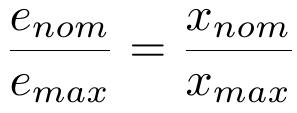

lo que, en unidades logarítmicas, nos lleva a una expresión muy sencilla:

Esta señal digital, *x*, es la que tendremos en el punto 4 de la figura, una vez ha pasado ya por el conversor analógico-digital, dentro de la parte digital del sistema de medida:

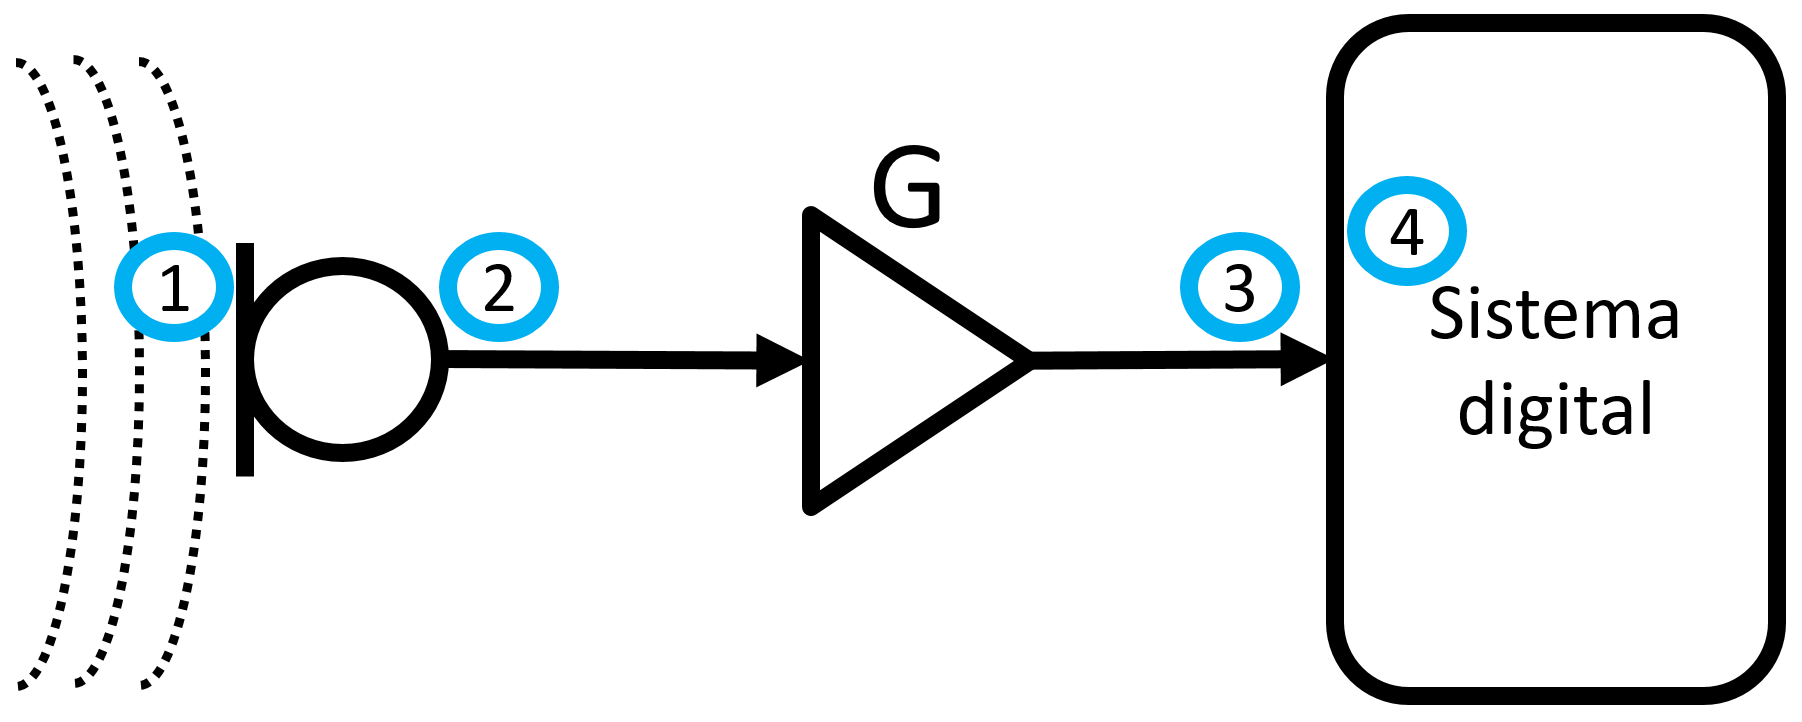

Vamos a suponer, en el ejemplo con el que estamos, que el nivel nominal lo vamos a hacer coincidir con esa presión referencia de 94 dB de nivel de presión sonora en el punto 1, y que el máximo valor representable en la parte digital lo hacemos corresponder con 0 dBFS. Si definimos un headroom de 12 dB, ¿cuál será la presión máxima, en Pascales, que podemos representar en el sistema digital sin sufrir un recorte? Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% Insert code
% headroom = 12;  % units?
% x_max_log = ???  % units?
% x_nom_log = ???  % units?
% e_nom_log = ???  % units?
% e_max_log = ???  % units?
% (...) ???
% p_1_max = ???  % units?


Asegúrate de que el resultado sea *p_1_max = 3.9905 Pa*.

Recuerda la definición del nivel de presión sonora:

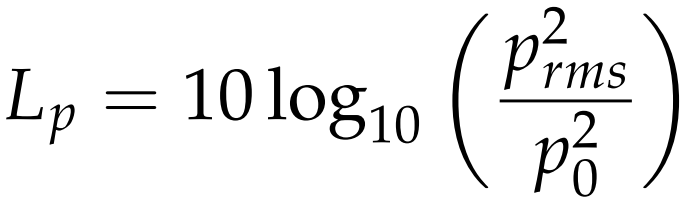

Calcula ahora, en decibelios, la diferencia entre el nivel de presión sonora máximo y el nivel de presión sonora nominal que puede gestionar el sistema de medida con el que trabajamos. Relaciónalo con el *headroom* del sistema digital y razona por qué tienen esa relación. Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% Insert code
% L_p_1_max = ??? // units??
% diferencia_log = ???L_p1???  // units??


Asegúrate de que el resultado sea *diferencia_log = 12 dB*.

### 2.5 Resumen

En esta sección 2 hemos:

- revisado cómo suele ser un sistema de medida hoy en día: un sistema analógico y otro digital.

- calculado la sensibilidad del micrófono y su dependencia con la frecuencia de trabajo y el ángulo de llegada del sonido.

- obtenido el valor de voltaje que tenemos a la entrada del sistema digital, tras pasar por un amplificador.

- establecido la relación entre los valores del sistema analógico y el digital, relacionándolos con el rango dinámico, sus valores nominal y máximo, y el *headroom*.

## 3. Bancos de filtros

En los equipos de medida, una de las formas habituales de estimar la energía en distintas bandas de frecuencia es haciendo uso de lo que se denomina un **banco de filtros**. Un banco de filtros de N bandas genera N señales distintas, cada una de las cuales recoge la energía de la banda de paso del filtro.

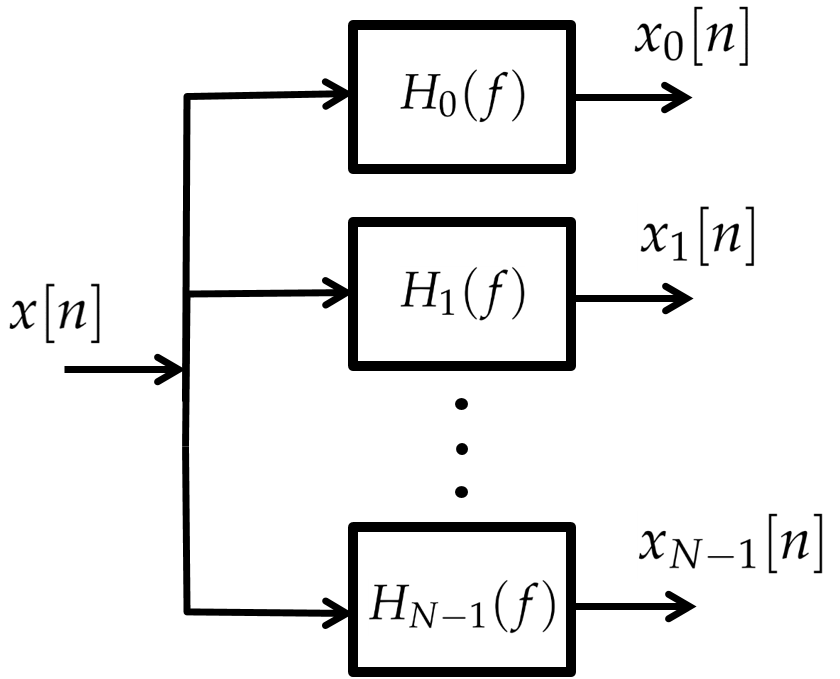

### 3.1 Representando bancos de filtros de factor de calidad constante

Carga este archivo *FilterBankCoefficientsOctave.mat* que contiene dos variables, *FilterBankCoefficients_1_octave* y *FilterBankCoefficients_1_3_octave*. Son dos objetos de procesado del *Audio Toolbox* de Matlab que contienen cada uno, respectivamente, los coeficientes que implementan el banco de filtros y que se pueden usar para hacer el filtrado.

 load FilterBankCoefficientsOctave.mat

Usa la función DrawFilterBankResponse para representar la respuesta del banco de filtros con un eje de frecuencias lineal. Observa primero su ayuda:

 help DrawFilterBankResponse

Representa la respuesta en frecuencia del banco de filtros de 1 octava con un eje de frecuencias lineal. Observa dónde están colocadas, con respecto al filtro, las frecuencias centrales. ¿Están justo en el centro de la banda de paso del filtro? ¿Por qué?

% INSERT CODE
%  DrawFilterBankResponse(???

 function DrawFilterBankResponse(auxFilterBankCoefficients, type);
    auxFilterBankCoefficients: an Octave Filter Bank block from the Audio
        Toolbox, that decomposes a signal into octave or fractional-octave subbands
    type: either 'log' or 'linear'
  Assumes:
    sampling frequency: 48 kHz
    reference frequency: 1 kHz



Representa ahora la respuesta en frecuencia del banco de filtros de 1 octava con un eje de frecuencias logarítmico

% INSERT CODE
%  DrawFilterBankResponse(???)



Obtén las frecuencias centrales así:

centerFrequencies = FilterBankCoefficients_1_octave.getCenterFrequencies

centerFrequencies = 	1.0e+04 *

    0.0032    0.0063    0.0126    0.0251    0.0501    0.1000    0.1995    0.3981    0.7943    1.5849


y las frecuencias de corte así:

bandEdgeFrequencies = FilterBankCoefficients_1_octave.getBandedgeFrequencies

bandEdgeFrequencies = 	1.0e+04 *

    0.0022    0.0045    0.0089    0.0178    0.0355    0.0708    0.1413    0.2818    0.5623    1.1220    2.2387


Compara esos valores con las gráficas que representan el banco de filtros.

### 3.2 Filtrando una señal usando bancos de filtros de factor de calidad constante

Genera un tono puro de 1000 Hz de 5 segundos, de amplitud 1, que comienza en el instante t = 0 segundos. Suponemos una frecuencia de muestreo de 48 kHz. Almacénalo en la variable *tono1kHz*.

% INSERTE EL CÓDIGO AQUÍ:
% f1 = 1e3;
% fs = 48e3;
% t = ....
%  tono1kHz = ...

Ahora vamos a filtrarlo usando un **banco de filtros de tercios de octava**. 

% tono1kHz_1_3_filteredMatrix = FilterBankFiltering(tono1kHz, FilterBankCoefficients_1_3_octave, 1);

¿Qué tamaño tiene la matriz *tono1kHz_1_3_filteredMatrix*? Las señales correspondientes a cada banda, ¿están en las filas o en las columnas de la matriz?

% INSERTE EL CÓDIGO AQUÍ:
% ???

Dibuja las primeras 1000 muestras de la señal correspondiente a la primera banda, las primeras 1000 muestras de señal de la banda número 14 y las primeras 1000 muestras de señal dela banda número 17. Usa *subplot* para dibujar las tres a la vez.

% INSERTE EL CÓDIGO AQUÍ:
% figure;
% subplot(311);plot(??????);title('Banda 1');
% subplot(???);plot(??????);title('Banda 14');shg
% subplot(???);plot(??????);title('Banda 17');shg


Comprueba qué frecuencias de corte y qué frecuencias centrales tienen cada una de las bandas representadas en la figura anterior:

% Vector with edge frequencies
frec_corte_1_3 = FilterBankCoefficients_1_3_octave.getBandedgeFrequencies;
% Vector with central frequencies
frec_central_1_3 = FilterBankCoefficients_1_3_octave.getCenterFrequencies;
% INSERTE EL CÓDIGO AQUÍ:


¿Qué tipo de señal contiene la señal de cada banda? ¿qué amplitud tienen? ¿por qué aparecen esas señales en bandas tan alejadas del tono de 1 kHz?

**EXTRA:**

Repite el filtrado en bandas, pero indica que no se compense el retardo de grupo de las bandas. Dibuja los comienzos de las señales de las bandas 1, 14 y 17, y discute qué ocurre.

### 3.3 Estimando el nivel de cada banda en un banco de filtros

Una forma muy usada de representar la energía espectral, si usamos un banco de filtros, es calcular el valor eficaz (*rms*) de la señal correspondiente a cada banda.

Calcula el valor eficaz de cada banda del tono de 1 kHz que hemos filtrado antes, *tono1kHz_1_3_filteredMatrix*, agrúpalos en un vector *bands_rms* y represéntalos todos juntos usando la función *bar*.

% INSERTE EL CÓDIGO AQUÍ:
% bands_rms es un vector columna con el valor eficaz de
% cada banda
% ??? MyRMScalculation(???)
% bands_rms = ???  
% figure;bar(bands_rms);shg


¿Qué valor eficaz tiene la banda de mayor energía? ¿A qué amplitud de tono se corresponde?

Vamos a crear una función *SPL_1_3_octave *que nos represente en una gráfica el nivel de presión sonora (SPL) en bandas de tercios de octava de la señal digital que obtenemos al medir un sonido. Integra el código que has programado antes.

Necesitaremos como parámetros de entrada:

    -> señal digital, acotada entre los valores -1 y +1

    -> valor dBFS correspondiente a la señal digital al medir 94 dB SPL a la entrada del sistema

Además de presentar la gráfica, debe devolver a la salida un vector con los valores en dB SPL de cada banda de tercio de octava:

*output_SPL_1_3_octave = SPL_1_3_octave(input_signal, ref_dBFS_94_dB_SPL);*

Pruébala con una señal en el sistema digital que corresponda a 5 segundos de un tono de 1 kHz, de amplitud 1, con una frecuencia de muestreo de 48 kHz. 

% INSERTE EL CÓDIGO AQUÍ:
% f1 = 1e3;
% fs = 48e3;
% Ts = 1/fs;
% t = ????
% tono1kHz = ???
% ref_dBFS_94_dB_SPL = ?????;  // units??
% output_SPL_1_3_octave = SPL_1_3_octave(tono1kHz, ref_dBFS_94_dB_SPL);


Comprueba que la banda con el nivel máximo de presión sonora tenga *106 dB SPL*, que es el valor máximo que el sistema puede gestionar sin recorte, como habíamos calculado antes

Carga la señal contenida en *tonos_3_4_5.wav*. Vamos a suponer que es la señal que se obtiene en el sistema digital cuando hacemos una medida con nuestro sistema.

[tonos_3_4_5, fs_3_4_5] = audioread('tonos_3_4_5.wav');

Representa con una gráfica de barras el nivel de presión sonora (SPL) que hemos medido, usando un banco de filtros de tercio de octava.

% INSERTE EL CÓDIGO AQUÍ:
% ref_dBFS_94_dB_SPL = ????  // units??
% output_SPL_1_3_octave = SPL_1_3_octave(tonos_3_4_5, ref_dBFS_94_dB_SPL);


Asegúrate de que el resultado sea, aproximadamente,* 79.97 dBSPL, 72.02 dBSPL y 78.04 dBSPL*, en las bandas de *500 Hz, 1 kHz y 2 kHz*, respectivamente. 

**E X T R A:**

Estima las amplitudes de los tonos que forman la señal *tonos_3_4_5*.

### 3.4 Ruido blanco y ruido rosa

Supón ahora que la señal de entrada en el sistema digital es la contenida en el archivo *ruido1.wav*. Razona si esta señal es un ruido blanco o un ruido rosa.

%Inserte el código aquí
% [ruido1, fs1] = audioread('ruido1.wav');
% ref_dBFS_94_dB_SPL = ????
% ruido1_SPL_1_3_octave = SPL_1_3_octave(ruido1, ????


Supón ahora que la señal de entrada en el sistema digital es la contenida en el archivo *ruido2.wav*. Razona si esta señal es un ruido blanco o un ruido rosa.

%Inserte el código aquí
% [ruido2, fs2] = audioread('ruido2.wav');
% ref_dBFS_94_dB_SPL = ????
% ruido1_SPL_1_3_octave = SPL_1_3_octave(ruido2, ????

### 3.5 Resumen

En esta sección 3 hemos visto:

- qué información está relacionada con un banco de filtros no uniforme, de calidad constante

- cómo filtrar una señal usando un banco de filtros

- cómo calcular y presentar en pantalla la energía contenida en cada una de las bandas

- cómo se distribuye la energía de un ruido blanco y un ruido rosa en un banco de filtros de factor de calidad constante

## 4. Ejemplos de calibración

### 4.1 Presentación en pantalla de una medida 

El sistema de medida de la sección 2 ha sido calibrado de forma que, cuando tenemos a su entrada un nivel de presión sonora de 94 dB, tengamos un nivel nominal de -12 dBFS en el sistema digital, ya que hemos fijado que el valor máximo se corresponda con 0 dBFS y tengamos 12 dB de *headroom*.

Supongamos que el sistema digital tiene que presentar por pantalla el nivel de presión que está midiendo:

valor_SPL = 94; disp(['Nivel SPL medido: ' num2str(valor_SPL)  ' dBSPL']);

Nivel SPL medido: 94 dBSPL


Indica los comandos necesarios para obtener el valor de nivel de presión sonora a mostrar en pantalla, dado un valor en dBFS en el sistema digital. Prueba con el valor -17.32 dBFS. Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% INSERTE EL CÓDIGO AQUÍ:
% valor_dBFS_max = 0;
% headroom = 12; % dB
% valor_dBFS_nom = valor_dBFS_max - headroom;  % units?
% valor_SPL_calibr = 94;  % units?
% valor_dBFS = -17.32;  % dBFS
% valor_SPL = ????  % units?
% disp(['Nivel SPL medido: ' num2str(valor_SPL)  ' dBSPL']);


Asegúrate de que el resultado sea *valor_SPL = 88.68 dBSPL*.

### 4.2 Calibrando el sistema y haciendo una medida

El sistema de medida, especialmente en su parte analógica, puede tener cambios en sus características debido a variaciones en la temperatura, la humedad y otros factores. Por eso, cuando vamos a realizar una medida, lo primero es **calibrar el sistema**. Vamos a ver qué ocurre si no lo hacemos y cómo evitarlo.

Seguimos trabajando con el sistema de medida anterior:

Primero vamos a preparar una función que agrupe los cálculos que hemos estado haciendo, y calcule el voltaje que se generará en el punto 3, dada una presión sonora en el punto 1.

Crea una función nueva con esta cabecera:

            *function voltage_3 = MyVoltage3calculation(pressureRMS, sensitivity_V_Pa, G_dB);*

donde *pressureRMS *será el valor eficaz de la señal de presión sonora registrada en el punto 1, *sensitivity_V_Pa *será la sensibilidad (total) del micrófono en V/Pa y *G_dB* la ganancia del amplificador en dB.

y completa estas líneas en el cuerpo de la función para que devuelva *voltage_3, *el valor eficaz del voltaje en el punto 3. Haz uso de todo lo que has trabajado en las secciones anteriores:

*            % voltage_2 = ???*

*            % voltage_2_dB = ???*

*            % voltage_3_dB = ???*

*            % voltage_3 = ???*

Asegúrate de que, por ejemplo, si ***pressureRMS = 1.0024 Pa***, *sensitivity_V_Pa = 1.6e-3 *y *G_dB = 3, *el resultado sea, aproximadamente, *voltage_3 = 0.0023 V, *como habíamos resuelto anteriormente.

**¿Qué ocurre si el sistema de medida que tenemos calibrado cambia de alguna forma? ¿Cómo podemos recalibrarlo?**

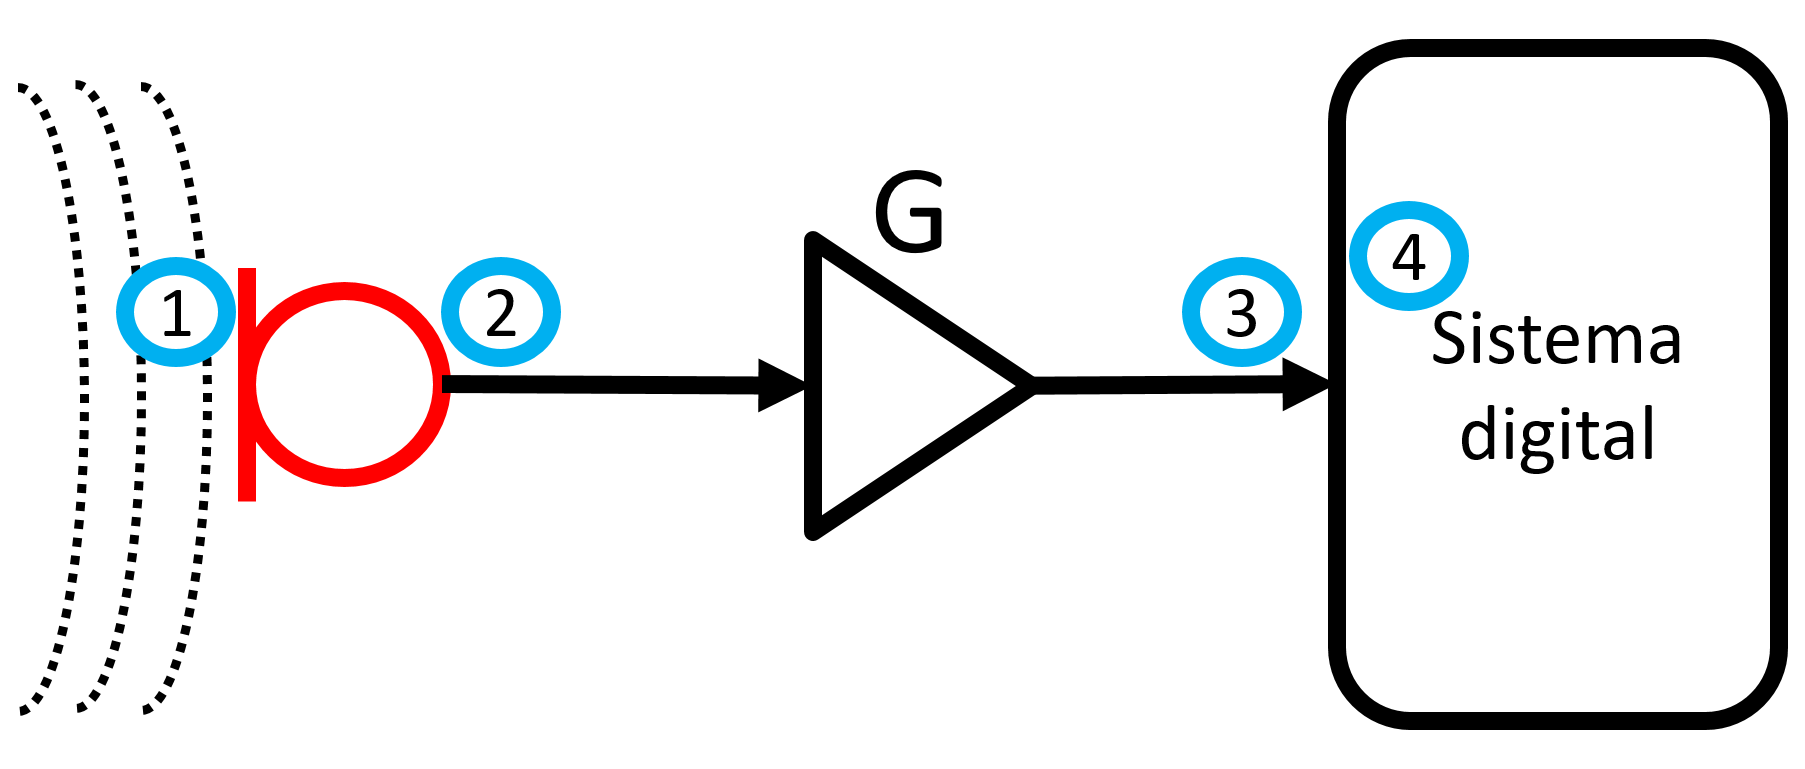

Supongamos ahora que cambiamos el micrófono en el sistema de medida que tenemos y que, cuando medimos un tono de 1 kHz con un nivel de presión sonora de 94 dB, obtenemos a la salida del micrófono (*punto 2*) un valor eficaz de voltaje de *14.1 mV*. Ajusta la ganancia del amplificador, a un valor *G_new*, para que el voltaje en el punto 3 sea el valor que tiene *e_nom_log* (aprox.* 0.0023 V), *como habíamos resuelto anteriormente. ¿Qué sensibilidad tenemos en el nuevo micrófono en su eje acústico a 1 kHz? Indica en cada operación qué unidades estás manejando, usando un comentario de matlab al final.

% INSERTE EL CÓDIGO AQUÍ:
% e_2 = 14.1e-3;  % mV
% e_2_log = ???  % units?
% e_3 = e_nom_log;  % V
% G_new = ???  % units?
% ???(...)???
% S = ???  % units?

Asegúrate de que el resultado sea *G_new = -15.8814 dB y la sensibilidad 14.1 mV/Pa*.

Supón ahora que mides un tono acústico de 1 kHz cuya valor eficaz de presión es de ***0.3 Pa*****. **Presenta por consola el resultado de la medida en el sistema digital actual, con el micrófono nuevo, tras pasar por todos los sistemas. Comprueba que la medida impresa en la consola coincide con la esperada.

% INSERTE EL CÓDIGO AQUÍ:
% pressure_rms = 0.3;  % Pa
% sensitivity = S_1kHz_un  %   units??
% voltage_3 = MyVoltage3calculation(?????) %   units??
% e_3_log = ??? %   units??
% diferencia_dB = ???? %   units??
% valor_dBFS_max = 0;  % dBFS
% headroom = 12; % dB
% valor_dBFS_nom = valor_dBFS_max - headroom;  % dBFS
% valor_SPL_calibr = 94;  % dBSPL
% valor_medido_dBFS = ??? %   units??
% valor_medido_SPL = ??? %   units??
% disp(['Nivel SPL medido: ' num2str(valor_medido_SPL,'%.1f')  ' dBSPL']);
% valor_entrada_SPL =??? %   units??
% disp(['Nivel SPL entrada: ' num2str(valor_entrada_SPL,'%.1f')  ' dBSPL']);


### 4.3 Resumen

En esta sección 4 hemos visto:

- cómo presentar en la consola un resultado en dB SPL, dado un valor en dBFS, teniendo en cuenta la calibración del sistemas

- cómo recalibrar un sistema si hay cambios en sus elementos

- cómo presentar en la consola el resultado en dB SPL, dada una presión sonora a la entrada, pasando por todo el sistema de medida completo (analógico y digital).